# TMS Data Analysis

This example shows you how to import and decode CAN data from BLF-files in MATLAB for analysis. The BLF-file used in this example was generated from the DEV1 testbench.

## Open the DBC-File

Open the database file describing the source CAN network using the [`canDatabase`](https://www.mathworks.com/help/vnt/ug/candatabase.html) function.

tld = pwd;
cd ../Databases/
% canDB = canDatabase(tld + "\Databases\" + "TMS_NODE2.dbc");
canDB = canDatabase("TMS_NODE2.dbc");

## Investigate the BLF-File

Retrieve and view information about the BLF-File. The [`blfinfo`](https://www.mathworks.com/help/vnt/ug/blfinfo.html) function parses general information about the format and contents of the Vector Binary Logging Format BLF-file and returns the information as a structure.

filename = "test101022-2.blf";
cd ../Logs/
binf = blfinfo(filename);
% binf = blfinfo(tld + "\Logs\" + filename);
% binf.ChannelList

## Read Data from BLF-File

The data of interest was logged from the powertrain bus which is stored in channel 2 of the BLF-file. Read the CAN data using the [`blfread`](https://www.mathworks.com/help/vnt/ug/blfread.html) function. You can also provide the DBC-file to the function call which will enable message name lookup and signal value decoding.

cd ../Logs/
blfData = blfread(filename, 1, "Database", canDB);
% blfData = blfread(tld + "\Logs\" + filename, 1, "Database", canDB);

## Repackage and Visualize Signal Values of Interest

Use the [`canSignalTimetable`](https://www.mathworks.com/help/vnt/ug/cansignaltimetable.html) function to repackage signal data from each unique message on the bus into a signal timetable. This example creates three individual signal timetables for the three messages of interest, "ABSdata", "EngineData" and "GearBoxInfo", from the CAN message timetable.

signalTimetable1 = canSignalTimetable(blfData, "TMS_PDO_1");
signalTimetable1(631:end,:) = []; % Trim to 1000 seconds manual based on timestamps
signalTimetable2 = canSignalTimetable(blfData, "TMS_PDO_2");
signalTimetable2(631:end,:) = [];
signalTimetable3 = canSignalTimetable(blfData, "TMS_PDO_3");
signalTimetable3(630:end,:) = [];
signalTimetable4 = canSignalTimetable(blfData, "TMS_PDO_4");
signalTimetable4(630:end,:) = [];


To visualize the signals of interest, columns from the signal timetables can be plotted over time for further analysis.

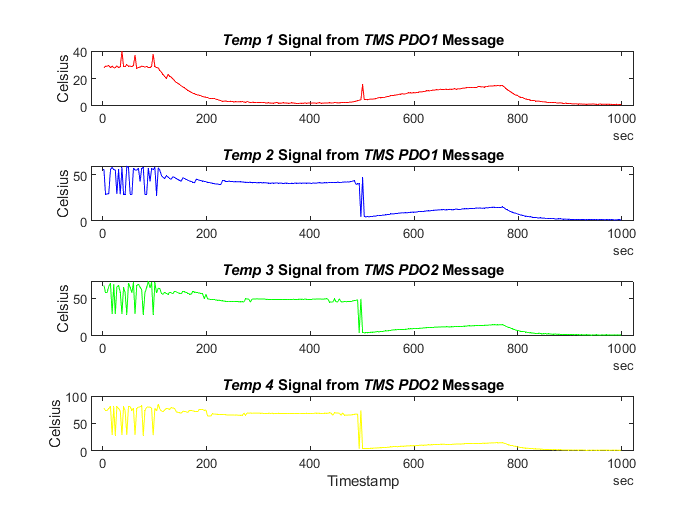

subplot(4, 1, 1)
plot(signalTimetable1.Time, signalTimetable1.Temp_1, "r")
title("{\itTemp 1} Signal from {\itTMS PDO1} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Celsius")
subplot(4, 1, 2)
plot(signalTimetable1.Time, signalTimetable1.Temp_2, "b")
title("{\itTemp 2} Signal from {\itTMS PDO1} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Celsius")
subplot(4, 1, 3)
plot(signalTimetable2.Time, signalTimetable2.Temp_3, "g")
title("{\itTemp 3} Signal from {\itTMS PDO2} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Celsius")

subplot(4, 1, 4)
plot(signalTimetable2.Time, signalTimetable2.Temp_4, "y")
title("{\itTemp 4} Signal from {\itTMS PDO2} Message", "FontWeight", "bold")
xlabel("Timestamp")
ylabel("Celsius")

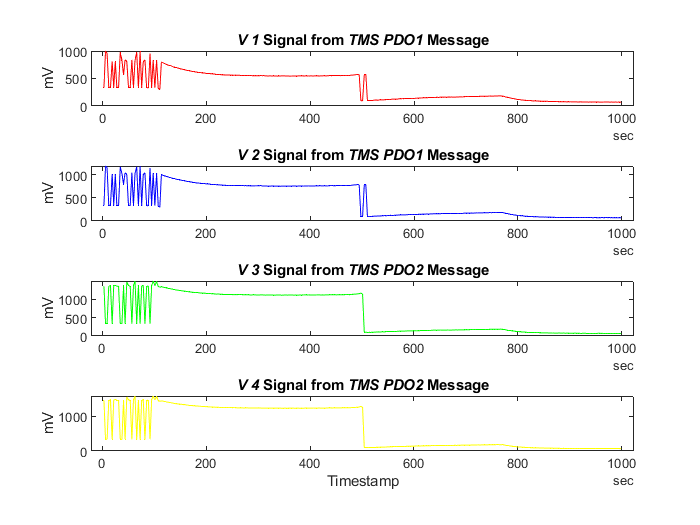


figure
subplot(4, 1, 1)
plot(signalTimetable3.Time, signalTimetable3.V1, "r")
title("{\itV 1} Signal from {\itTMS PDO1} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("mV")
subplot(4, 1, 2)
plot(signalTimetable3.Time, signalTimetable3.V2, "b")
title("{\itV 2} Signal from {\itTMS PDO1} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("mV")
subplot(4, 1, 3)
plot(signalTimetable4.Time, signalTimetable4.V3, "g")
title("{\itV 3} Signal from {\itTMS PDO2} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("mV")

subplot(4, 1, 4)
plot(signalTimetable4.Time, signalTimetable4.V4, "y")
title("{\itV 4} Signal from {\itTMS PDO2} Message", "FontWeight", "bold")
xlabel("Timestamp")
ylabel("mV")

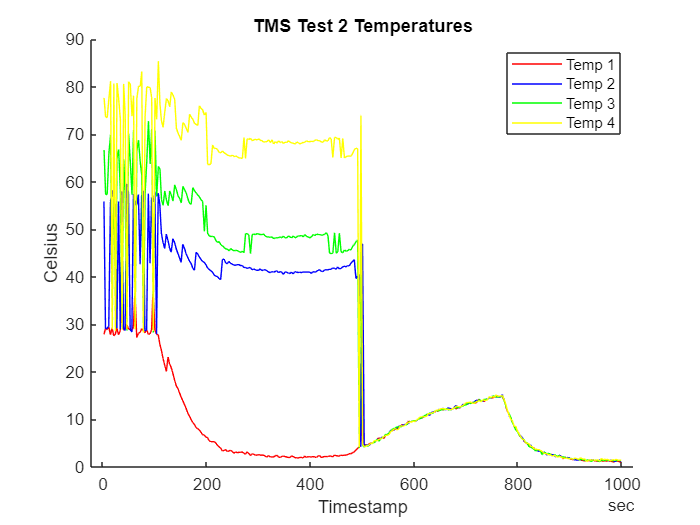

figure
hold on
title("TMS Test 2 Temperatures")
plot(signalTimetable1.Time, signalTimetable1.Temp_1, "r")
plot(signalTimetable1.Time, signalTimetable1.Temp_2, "b")
plot(signalTimetable2.Time, signalTimetable2.Temp_3, "g")
plot(signalTimetable2.Time, signalTimetable2.Temp_4, "y")
legend("Temp 1", "Temp 2", "Temp 3", "Temp 4")
xlabel("Timestamp")
ylabel("Celsius")

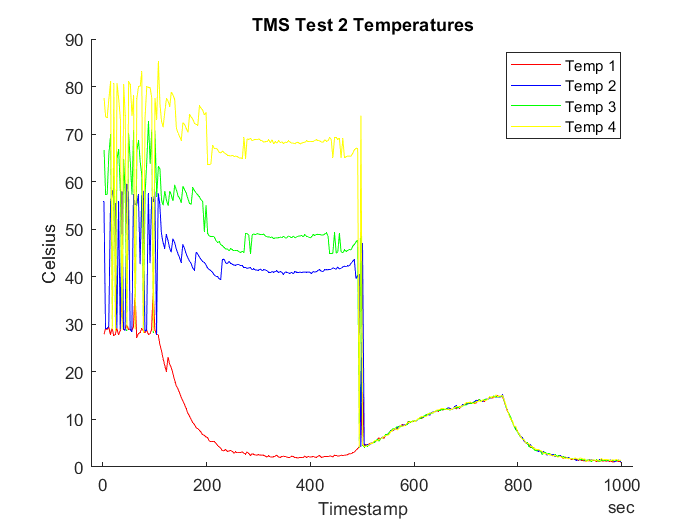


figure
hold on
title("TMS Test 2 Temperatures")
plot(signalTimetable1.Time, signalTimetable1.Temp_1, "r")
plot(signalTimetable1.Time, signalTimetable1.Temp_2, "b")
plot(signalTimetable2.Time, signalTimetable2.Temp_3, "g")
plot(signalTimetable2.Time, signalTimetable2.Temp_4, "y")
legend("Temp 1", "Temp 2", "Temp 3", "Temp 4")
xlabel("Timestamp")
ylabel("Celsius")

Get NI data

filename = "test101022-2.mat";
cd ../Logs/
% load(tld + "\Logs\" + filename);
load(filename);


nidata = horzcat(time, data)

nidata =          0   21.7725   21.5570    3.3627    1.5985
    0.0714   21.7725   21.5570    3.3761    1.5665
    0.1429   21.7725   21.5570    3.3735    1.5738
    0.2143   21.7676   21.5700    3.3735    1.5706
    0.2857   21.7676   21.5700    3.3764    1.5494
    0.3571   21.7676   21.5700    3.3856    1.5431
    0.4286   21.7831   21.5690    3.3621    1.5858
    0.5000   21.7831   21.5690    3.3672    1.5491
    0.5714   21.7831   21.5690    3.3719    1.5754
    0.6429   21.7703   21.5751    3.3946    1.5301


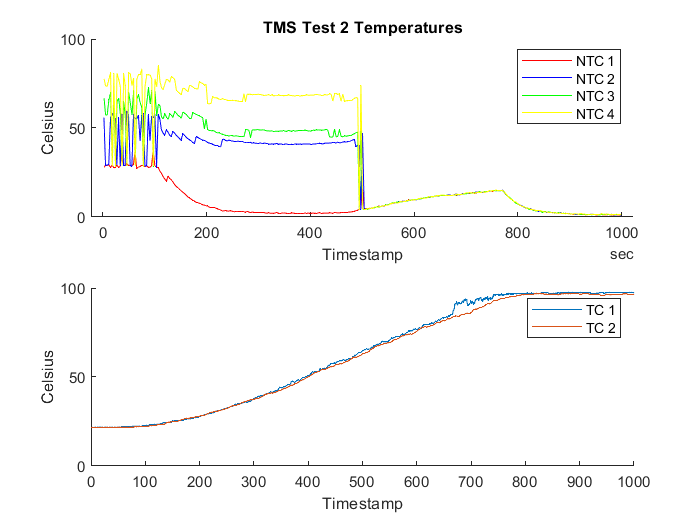

figure
hold on
% title("TMS Test 2 Temperatures")
subplot(2,1,1)
hold on
title("TMS Test 2 Temperatures")
plot(signalTimetable1.Time, signalTimetable1.Temp_1, "r")
plot(signalTimetable1.Time, signalTimetable1.Temp_2, "b")
plot(signalTimetable2.Time, signalTimetable2.Temp_3, "g")
plot(signalTimetable2.Time, signalTimetable2.Temp_4, "y")
legend("NTC 1", "NTC 2", "NTC 3", "NTC 4")
% xlim([0, 1000])
ylim([0 100])
xlabel("Timestamp")
ylabel("Celsius")
subplot(2,1,2)
hold on
plot(nidata(:,1), nidata(:,2))
plot(nidata(:,1), nidata(:,3))
% xlim([0, 1000])
ylim([0 100])
legend("TC 1", "TC 2");
xlabel("Timestamp")
ylabel("Celsius")

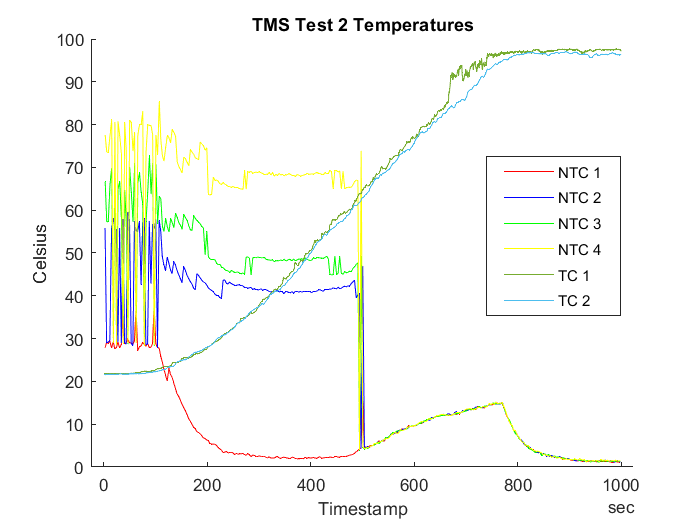


figure
hold on
title("TMS Test 2 Temperatures")
plot(signalTimetable1.Time, signalTimetable1.Temp_1, "r")
plot(signalTimetable1.Time, signalTimetable1.Temp_2, "b")
plot(signalTimetable2.Time, signalTimetable2.Temp_3, "g")
plot(signalTimetable2.Time, signalTimetable2.Temp_4, "y")
plot(nidata(:,1), nidata(:,2))
plot(nidata(:,1), nidata(:,3))
ylim([0 100])
legend("NTC 1", "NTC 2", "NTC 3", "NTC 4", "TC 1", "TC 2");
legend('Position',[0.69395,0.39736,0.19275,0.30579])
xlabel("Timestamp")
ylabel("Celsius")

NTC 1

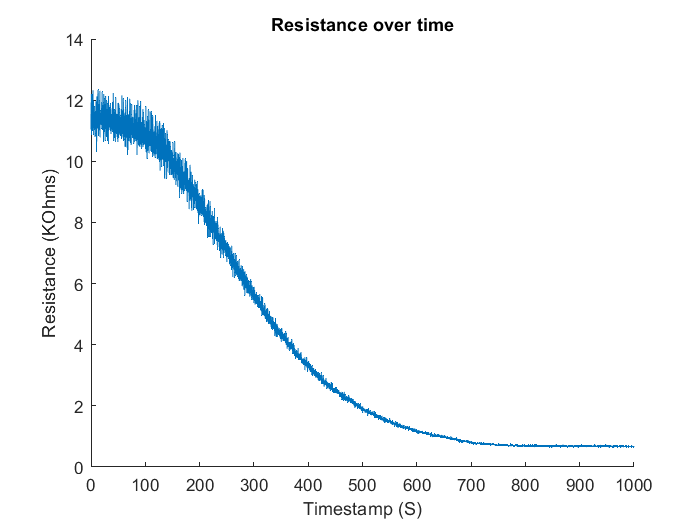

r1 = 10000;
vdd = nidata(:,4);
vdiv = nidata(:,5);
rntc = (vdd*r1)./(vdiv)-r1;

figure
hold on
title("Resistance over time")
plot(nidata(:,1), rntc/1000)
xlabel("Timestamp (S)")
ylabel("Resistance (KOhms)")

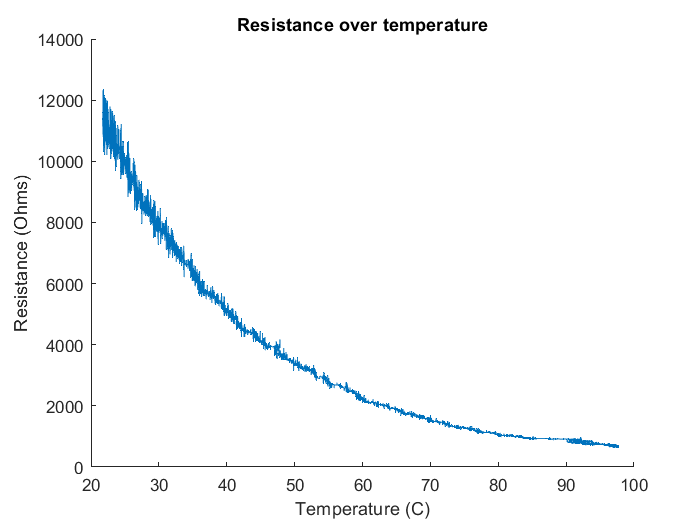

figure
hold on
title("Resistance over temperature")
plot(nidata(:,2),rntc)
xlabel("Temperature (C)")
ylabel("Resistance (Ohms)")

Smooth data

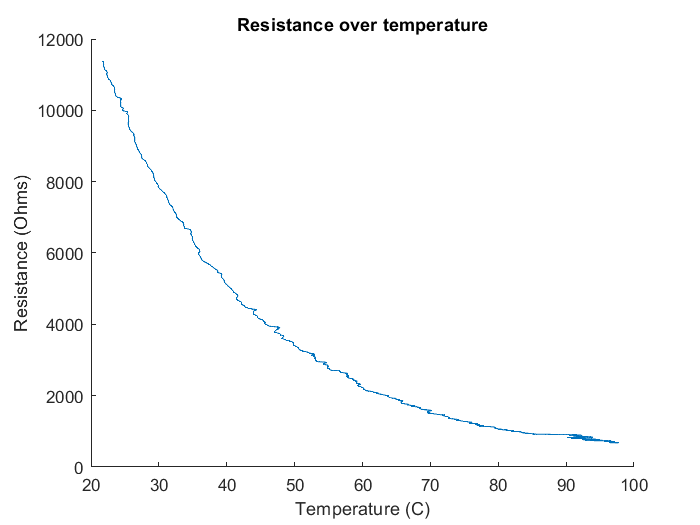

% Smooth input data
sm_ntc = smoothdata(rntc,"gaussian","SmoothingFactor",0.05);
figure
hold on
title("Resistance over temperature")
plot(nidata(:,2),sm_ntc)
xlabel("Temperature (C)")
ylabel("Resistance (Ohms)")

Smooth data

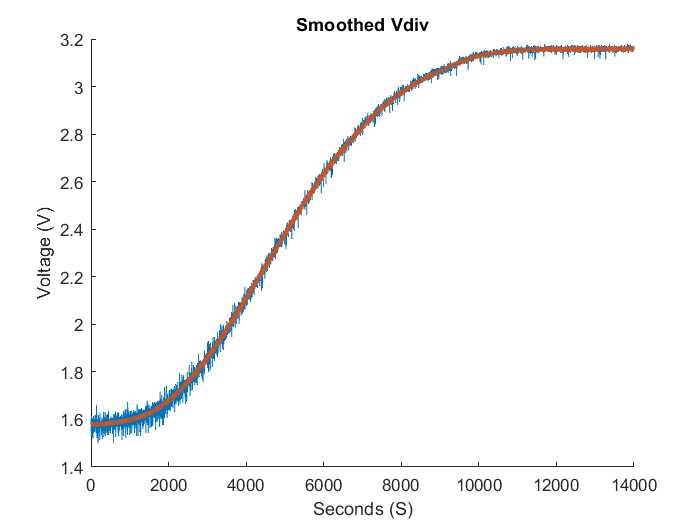

% Smooth input data
sm_vdiv = smoothdata(vdiv,"gaussian","SmoothingFactor",0.05);
figure
hold on
title("Smoothed Vdiv")
plot(vdiv)
plot(sm_vdiv, LineWidth=3)
xlabel("Seconds (S)")
ylabel("Voltage (V)")

`C(x) = 18.352x^3-69.323x^2+121.29x-7.3735`

 p1 =       34.12

p1 = 34.1200

 p2 =      -295.4

p2 = -295.4000

 p3 =       952.7

p3 = 952.7000

 p4 =       -1326

p4 = -1326

 p5 =         691

p5 = 691

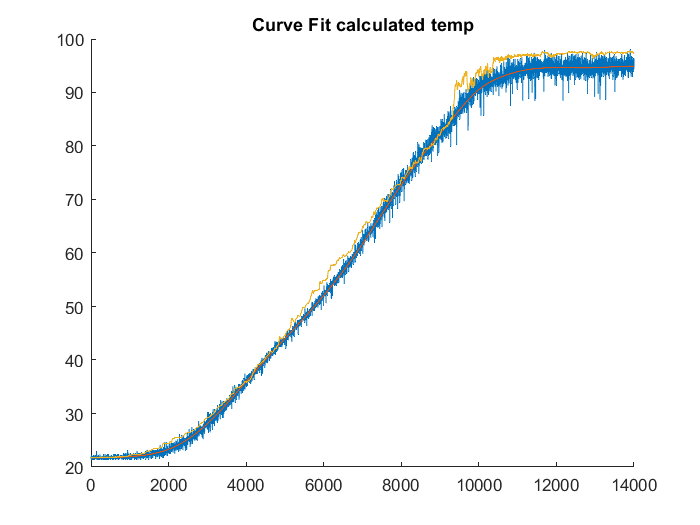


x = vdiv;
calc_temp = p1.*x.^4 + p2.*x.^3 + p3.*x.^2 + p4.*x + p5;

y = sm_vdiv;
calc_temp2 = p1.*y.^4 + p2.*y.^3 + p3.*y.^2 + p4.*y + p5;

figure
hold on
title("Curve Fit calculated temp")
plot(calc_temp)
plot(calc_temp2)
plot(temp)

Residuals

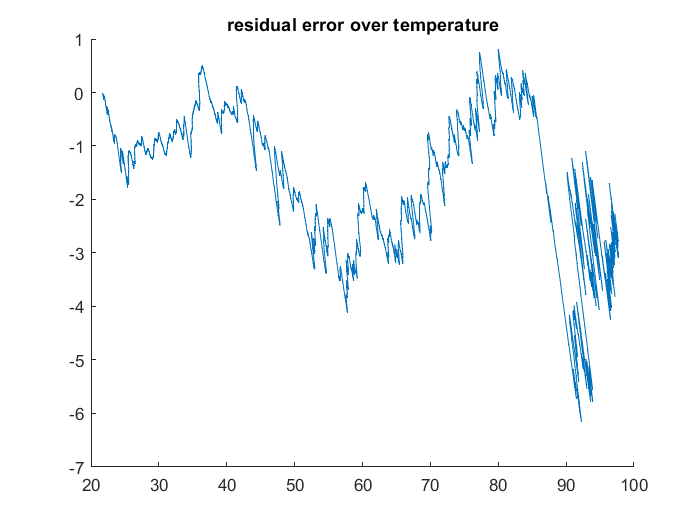

residuals = calc_temp2 - temp;
figure
hold on
title("residual error over temperature")
plot(nidata(:,2),residuals)